clear all;
close all;

CityNum=48; 
inn=30; %初始种群大小  
gnmax=667;  %最大代数  
pc=0.8; %交叉概率  
pm=0.5; %变异概率  
[dislist,Clist]=tsp(CityNum); 

%产生初始种群  
s=zeros(inn,CityNum);  
for i=1:inn  
    s(i,:)=randperm(CityNum);  
end  
[~,p]=objf(s,dislist);  
  
gn=1;  
ymean=zeros(gn,1);  
ymax=zeros(gn,1);  
xmax=zeros(inn,CityNum);  
scnew=zeros(inn,CityNum);  
smnew=zeros(inn,CityNum);
tic
while gn<gnmax+1  
   for j=1:2:inn  
      seln=sel(p);  %选择操作  
      scro=cro(s,seln,pc);  %交叉操作  
      scnew(j,:)=scro(1,:);  
      scnew(j+1,:)=scro(2,:);  
      smnew(j,:)=mut(scnew(j,:),pm);  %变异操作  
      smnew(j+1,:)=mut(scnew(j+1,:),pm);  
   end  
   s=smnew;  %产生了新的种群  
   [f,p]=objf(s,dislist);  %计算新种群的适应度  
   %记录当前代最好和平均的适应度  
   [fmax,nmax]=max(f);  
   ymean(gn)=1000/mean(f);  
   ymax(gn)=1000/fmax;  
   %记录当前代的最佳个体  
   x=s(nmax,:);  
   xmax(gn,:)=x;  
   %drawTSP(Clist,x,ymax(gn),gn,0);  
   gn=gn+1;  
end
toc

历时 1.583426 秒。


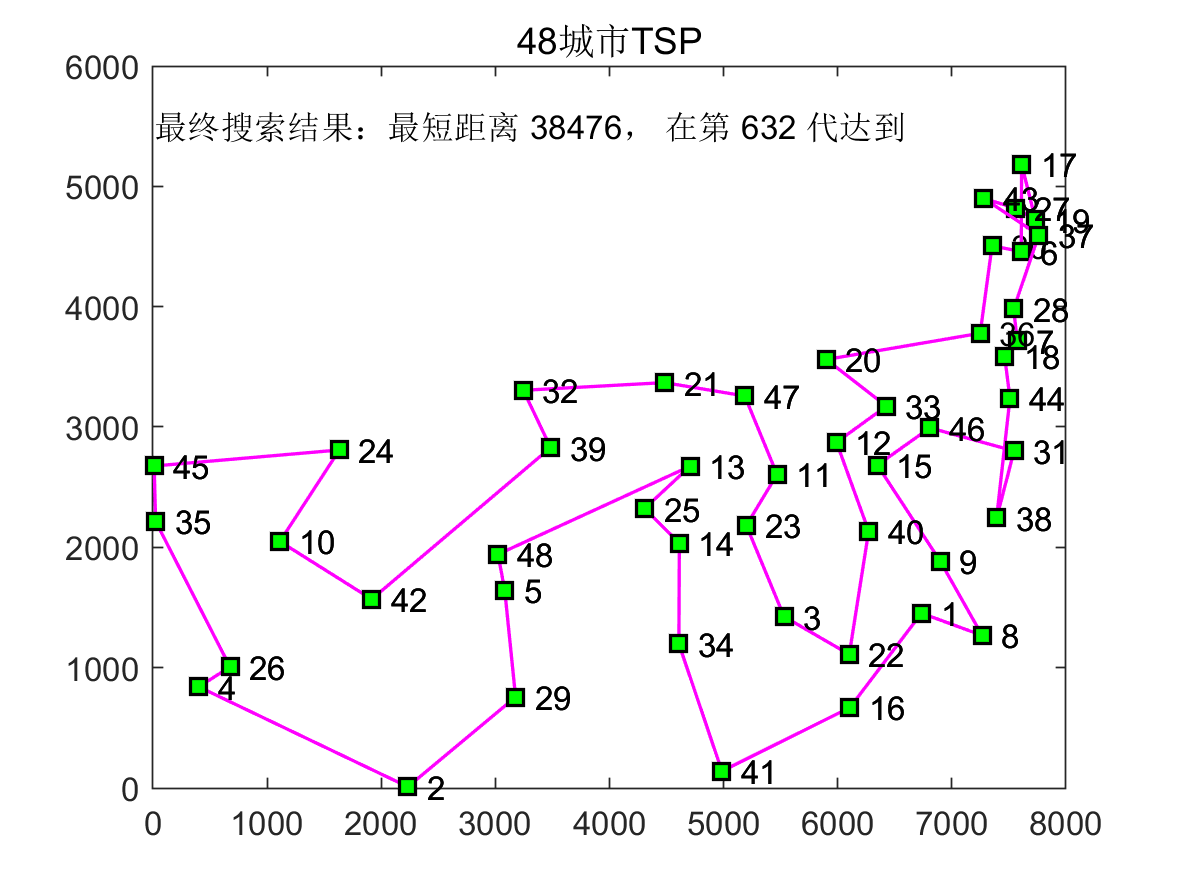

[min_ymax,index]=min(ymax);  
drawTSP(Clist,xmax(index,:),min_ymax,index,1);


% figure(2);  
% plot(ymax,'r'); hold on;  
% plot(ymean,'b');grid;  
% title('搜索过程');  
% legend('最优解','平均解');  
fprintf('遗传算法得到的最短距离:%.2f\n',min_ymax);  

遗传算法得到的最短距离:38476.00


fprintf('遗传算法得到的最短路线');  

遗传算法得到的最短路线

disp(xmax(index,:));  

  列 1 至 6

    30     6    17    19    27    43

  列 7 至 12

    37    28     7    18    44    38

  列 13 至 18

    31    46    15     9     8     1

  列 19 至 24

    16    41    34    14    25    13

  列 25 至 30

    48     5    29     2     4    26

  列 31 至 36

    35    45    24    10    42    39

  列 37 至 42

    32    21    47    11    23     3

  列 43 至 48

    22    40    12    33    20    36

